# Quantitative Methods for Finance

2025 Marina Dolfin

# QMF2_4_Modelling_Regression_TestingCAPM

## Case study on Capital Asset Pricing Model

The Capital Asset Pricing Model (CAPM) establishes a linear relationship between the expected return of a risky asset and its exposure to market risk.

It assumes investors are only rewarded for systematic (market) risk, while idiosyncratic (firm-specific) risk can be diversified away.

Theoretical form


$$\mathbb E [R_i]=R_f + \beta_i\,\mathbb E [R_m -R_f]$$


$\mathbb E [R_i]$: expected return of the asset

$\mathbb E [R_m]$: expected return of the market

$R_f$: risk-free rate

$\beta_i$ → systematic risk coefficient, measuring how sensitively the asset co-moves with the market


$$\beta i=Cov(Ri,Rm)Var(Rm)\beta_i = \frac{\mathrm{Cov}(R_i, R_m)}{\mathrm{Var}(R_m)}\beta i=Var(Rm)Cov(Ri,Rm)$$


The expected excess return of an asset equals its exposure to market risk (β) times the market risk premium.

Empirical version (testable equation)

Since expectations are not directly observable, we replace them with historical realized returns and add an error term:


$$Ri,t-Rf,t=\alpha +\beta \,(Rm,t-Rf,t)+\varepsilon tR_{i,t} - R_{f,t} = \alpha + \beta\,(R_{m,t} - R_{f,t}) + \varepsilon_tRi,t-Rf,t=\alpha +\beta (Rm,t-Rf,t)+\varepsilon t$$


$\alpha$ → intercept (Jensen's alpha), measuring abnormal performance

$\beta$ → systematic risk coefficient

$\varepsilon$ → idiosyncratic error term

We estimate $\alpha$ and $\beta$ using Ordinary Least Squares (OLS) —

an unconstrained quadratic optimization method that minimizes the sum of squared residuals.

In empirical analysis we use proxies for the unobservable theoretical quantities:

Theoretical quantity

Proxy in practice

Ticker example

$R_f$: Risk-free rate

3-month U.S. Treasury Bill yield

^IRX

$R_m$: Market portfolio

Broad market index (e.g. S&P 500)

^GSPC or ^SP500TR

$R_i$: Asset return

Individual stock

e.g. NVDA

Learning objective:

Use real data to estimate a company's systematic risk (β) and abnormal performance (α) by interpreting the CAPM as an optimization problem solved through OLS.

clear; close all;

% Parameters
startDate = '01-Jan-2023';
endDate   = '01-Mar-2024';
interval  = '1d';

% Use adjusted close
fields = {'close'};

% Fetch: risk-free (IRX), market (SP500TR preferred; fallback GSPC), stock (NVDA)
FIR  = fetchYahooFinanceData('^IRX',  startDate, endDate, interval, fields);   % IRX in percent
MKT  = fetchYahooFinanceData('^SP500TR', startDate, endDate, interval, fields);% total return index
STK  = fetchYahooFinanceData('NVDA', startDate, endDate, interval, fields);



% Convert IRX (percent, BDY) to daily simple rf (approx)
rf_daily = table2array(FIR(:,2))/100/252;

% Compute (simple) daily returns from AdjClose
Rm = tick2ret(MKT.Close);  % market return
Ri = price2ret(STK.Close);  % stock return


rf = rf_daily(2:end);                      % align lengths after ret


% Excess returns
Excess_market = Rm - rf;
Excess_stock = Ri - rf;


% OLS (includes intercept by default)
T = table(Excess_market, Excess_stock,'VariableNames',{'Excess_market','Excess_stock'});
mdl = fitlm(T,'Excess_stock ~ Excess_market')

mdl = Linear regression model:
    Excess_stock ~ 1 + Excess_market

Estimated Coefficients:
                     Estimate        SE        tStat       pValue  
                     _________    _________    ______    __________

    (Intercept)      0.0038016    0.0014376    2.6443     0.0086337
    Excess_market       2.1321       0.1762      12.1    1.5804e-27


Number of observations: 290, Error degrees of freedom: 288
Root Mean Squared Error: 0.0243
R-squared: 0.337,  Adjusted R-Squared: 0.335
F-statistic vs. constant model: 146, p-value = 1.58e-27

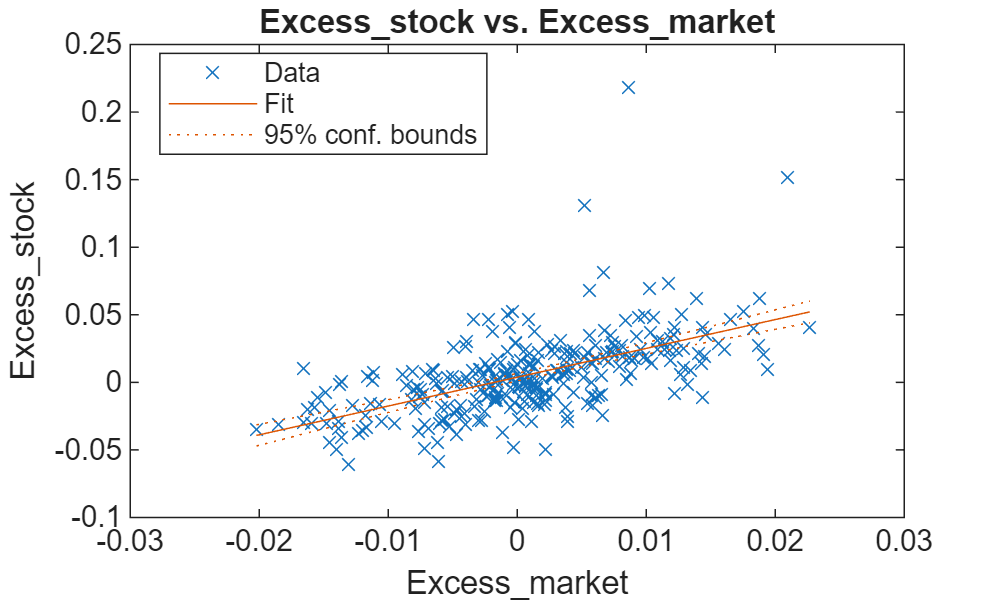


% alpha = intercept, beta = slope on Rx_m
alpha_hat = mdl.Coefficients.Estimate(1);
beta_hat  = mdl.Coefficients.Estimate(2);

plot(mdl)

## Interpretation of the result - statistical significance of $\alpha$

I will check with the linear regression the statistical significance of $\alpha$.


$$H_0 \,:\,\alpha =0\quad H_A\,:\,\alpha\neq 0$$


To do that one need to do hypothesis testing using a t-test. 

Test the statistic $t_{statistic}=\frac{\tilde\alpha-H_0}{SE(\tilde\alpha)}$ to be compared with the critical values from a t-student distribution

Rejection rule


$$|t_{statistic}|\geq critical\,value$$



$$t_{statistic}>c.v.\:or\: t_{statistic}<-c.v.$$


## Testing the slope coefficient on market excess return:


$$H_0 \,:\,\beta =1\quad H_A\,:\,\beta\neq 1$$


coeffs = mdl.Coefficients;
t_alpha = coeffs.tStat(1);
p_alpha = coeffs.pValue(1);

t_beta  = (coeffs.Estimate(2) - 1) / coeffs.SE(2);
p_beta  = 2 * (1 - tcdf(abs(t_beta), mdl.DFE));

fprintf('t(alpha) = %.3f, p(alpha) = %.3f\n', t_alpha, p_alpha);

t(alpha) = 2.644, p(alpha) = 0.009


fprintf('t(beta=1) = %.3f, p(beta=1) = %.3f\n', t_beta, p_beta);

t(beta=1) = 6.425, p(beta=1) = 0.000


In the CAPM framework,  a statistically significant positive α is sometimes interpreted as "managerial skill" or "mispricing," but it may also reflect model limitations (e.g., omitted risk factors).

 function stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields)
% fetchYahooFinanceData Fetches historical stock data from Yahoo Finance.
%
%   stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields)
%
%   Parameters:
%       symbol     - Stock symbol as a string (e.g., 'AAPL').
%       startDate  - Start date as a string or datetime ('dd-mmm-yyyy' format).
%       endDate    - End date as a string or datetime ('dd-mmm-yyyy' format).
%       interval   - Data interval: '1d' (daily), '1wk' (weekly), '1mo' (monthly).
%       fields     - Cell array of strings -i.e.curly brackets needed to
%       enter input, specifying data fields to retrieve, one or more
%                    Valid fields: 'open', 'close', 'high', 'low',
%                    'volume'. e.g.{'open', 'high', 'low', 'close', 'volume'}, 
%
%   Returns:
%       stockData  - Table containing the date and requested data fields.

    % Validate inputs
    if nargin < 5
        error('All five arguments (symbol, startDate, endDate, interval, fields) are required.');
    end

    % Convert dates to datetime if necessary
    if ischar(startDate) || isstring(startDate)
        startDate = datetime(startDate, 'InputFormat', 'dd-MMM-yyyy');
    end
    if ischar(endDate) || isstring(endDate)
        endDate = datetime(endDate, 'InputFormat', 'dd-MMM-yyyy');
    end

    % Validate interval
    validIntervals = {'1d', '1wk', '1mo'};
    if ~ismember(interval, validIntervals)
        error('Invalid interval. Choose from ''1d'', ''1wk'', or ''1mo''.');
    end

    % Convert dates to UNIX timestamps
    startNum = posixtime(datetime(startDate));
    endNum = posixtime(datetime(endDate));

    % Construct the URL
    url = ['https://query1.finance.yahoo.com/v8/finance/chart/' symbol ...
           '?period1=' num2str(floor(startNum)) '&period2=' num2str(floor(endNum)) '&interval=' interval];

    % Set web options with a user-agent header to mimic a browser
    options = weboptions('ContentType', 'json', 'UserAgent', 'Mozilla/5.0');

    % Fetch data
    try
        data = webread(url, options);
    catch ME
        error('Failed to retrieve data: %s', ME.message);
    end

    % Check for errors in response
    if isempty(data.chart.result) || ~isempty(data.chart.error)
        error('Failed to retrieve data. Please check the stock symbol and date range.');
    end

    % Extract the result
    result = data.chart.result;
    if iscell(result)
        result = result{1};
    elseif isstruct(result) && numel(result) > 1
        result = result(1);
    end

    % Extract timestamps
    if isfield(result, 'timestamp')
        timestamps = result.timestamp;
    else
        error('No timestamp data available.');
    end

    % Convert timestamps to datetime
    dates = datetime(timestamps, 'ConvertFrom', 'posixtime', 'TimeZone', 'UTC');

    % Access indicators
    if isfield(result, 'indicators') && isfield(result.indicators, 'quote')
        quote = result.indicators.quote;
        if iscell(quote)
            quote = quote{1};
        elseif isstruct(quote) && numel(quote) > 1
            quote = quote(1);
        end
    else
        error('No quote data available.');
    end

    % Initialize table with dates
    stockData = table(dates, 'VariableNames', {'Date'});

    % Ensure fields are in lowercase
    fields = lower(fields);

    % Valid fields in the data
    validFields = fieldnames(quote);

    % For each requested field, extract the data
    for i = 1:length(fields)
        field = fields{i};
        if ismember(field, validFields)
            fieldData = quote.(field);
            fieldData = fieldData(:);  % Ensure column vector
            % Handle missing data
            if length(fieldData) < length(dates)
                fieldData(end+1:length(dates)) = NaN;
            elseif length(fieldData) > length(dates)
                fieldData = fieldData(1:length(dates));
            end
            % Append to table with capitalized field name
            stockData.(capitalizeFirstLetter(field)) = fieldData;
        else
            warning('Field "%s" is not available in the data.', field);
            % Fill with NaNs if field is missing
            stockData.(capitalizeFirstLetter(field)) = NaN(height(stockData), 1);
        end
    end

    % Remove rows where all data fields are NaN
    dataFields = stockData.Properties.VariableNames(2:end);
    validRows = any(~isnan(stockData{:, dataFields}), 2);
    stockData = stockData(validRows, :);

    % Reset the datetime to remove time zone information
    stockData.Date.TimeZone = '';

end

function outStr = capitalizeFirstLetter(inStr)
% Helper function to capitalize the first letter of a string
    outStr = lower(inStr);
    if ~isempty(outStr)
        outStr(1) = upper(outStr(1));
    end
end
